clear
clc
close all


freqcubesat1 = 1134; % [Hz].

m_em = 0.94; % [kg] Masa plato + bobina
m_cubesat = 1.33; %[kg] Masa Cubesat
m_shaker = 97.5; %[kg]
%m_modal_cubesat = 1
kem = 15761; % [N/m]
%kem = 10000;
% kc = (2*pi*freqcubesat1)^2*m_modal_cubesat %[N/m]
%kc = 2.7955e+07;
kc = 4e+08/6; % [N/M]
k_shaker = 500; % [N/M]

M = [m_cubesat 0 0;
    0 m_em 0;
    0 0 m_shaker];
K = [kc -kc 0;
    -kc kc+kem -kem;
    0 -kem kem+k_shaker];

K_motor = 51.6; %[N/A] [Vs/m] constante de back EMF y de fuerza (valen lo mismo)
g = 9.81; %[m/s^2] Aceleración de la gravedad

R = 3; %[Ohm] Resistencia del bobinado
L = 1.9e-3; %[H] Inductancia del bobinado (medida a 1000Hz)

Pot_max = 75 ; %[W] Potencia máxima
I_max = sqrt(Pot_max/R); % [A]
V_max = 40; % [V]


[autovec,autoval]=eig(K,M);
w=diag(autoval^0.5);
f = w/(2*pi);


dt=0.0001;
T=5;
t=0:dt:T;

x0=zeros(3,1); %%[-0.557880413175386;0.789602216518309;0];
v0=zeros(3,1);

w=diag(autoval^0.5);
% autovec = tu matriz de autovectores (cada columna un modo)



y0=autovec'*M*x0;

y00=autovec'*M*v0;

zittam1 = 0.2;
zittam2 = 0.2;
zittam3 = 0.07;

zitta = [zittam1;zittam2;zittam3];

wd = zeros(length(w),1);

for i = 1:length(w)
    wd(i) = w(i)*sqrt(1-zitta(i)^2);
end

q1 = [exp(-zitta(1)*w(1)*t) .* y0(1) .* cos(wd(1)*t);
      exp(-zitta(2)*w(2)*t) .* y0(2) .* cos(wd(2)*t);
      exp(-zitta(3)*w(3)*t) .* y0(3) .* cos(wd(3)*t)];

q2 = [exp(-zitta(1)*w(1)*t) .* zitta(1)/(sqrt(1-zitta(1)^2)) .* sin(wd(1)*t) .* y0(1);
      exp(-zitta(2)*w(2)*t) .* zitta(2)/(sqrt(1-zitta(2)^2)) .* sin(wd(2)*t) .* y0(2);
      exp(-zitta(3)*w(3)*t) .* zitta(3)/(sqrt(1-zitta(3)^2)) .* sin(wd(3)*t) .* y0(3)];

q3 = [y00(1)/wd(1) .* sin(wd(1)*t) .* exp(-zitta(1)*w(1)*t);
      y00(2)/wd(2) .* sin(wd(2)*t) .* exp(-zitta(2)*w(2)*t);
      y00(3)/wd(3) .* sin(wd(3)*t) .* exp(-zitta(3)*w(3)*t)];




q=q1+q2+q3;

X=autovec*q;

          
Cmodal = [2*zitta(1)*w(1) 0 0;
          0 2*zitta(2)*w(2) 0;
          0 0 2*zitta(3)*w(3);];
          
C = M*autovec*Cmodal*autovec'*M;


n = size(M,1);
x0=[0;0;0];
v0=zeros(n,1);
A = [zeros(n), eye(n);
     -M\K, -M\C];
Bu = [zeros(n,1); M\eye(n)*[0; 1; -1]]; % por ejemplo, fuerza en masa 2
Bd = [zeros(n,1); M\eye(n)*[0; -1; 0]]; % por ejemplo, fuerza perturbadora en masa 2

B =[Bu,Bd];

% Armamos la nueva fila del C_out para aceleración
C_acc = -inv(M)*[K,C]  % [x, x_dot]

C_acc = 	1.0e+07 *

   -5.0125    5.0125         0   -0.0001    0.0001    0.0000
    7.0922   -7.0939    0.0017    0.0001   -0.0001    0.0000
         0    0.0000   -0.0000    0.0000    0.0000   -0.0000



% Nueva matriz C de salida
Cc = [eye(6); 
         C_acc]

Cc = 	1.0e+07 *

    0.0000         0         0         0         0         0
         0    0.0000         0         0         0         0
         0         0    0.0000         0         0         0
         0         0         0    0.0000         0         0
         0         0         0         0    0.0000         0
         0         0         0         0         0    0.0000
   -5.0125    5.0125         0   -0.0001    0.0001    0.0000
    7.0922   -7.0939    0.0017    0.0001   -0.0001    0.0000
         0    0.0000   -0.0000    0.0000    0.0000   -0.0000



% D de salida (sin entrada directa)
Du = [zeros(7,1);1/M(2,2);-1/M(3,3)];
Dd = [zeros(7,1);-1/M(2,2);0];
D = [Du,Dd];
sys = ss(A, [Bu,Bd], Cc, D);
f_transf = tf(sys)

f_transf =
 
  From input 1 to output...
                        663.7 s^3 + 5.333e07 s^2 + 4.778e07 s + 2.735e08
   1:  ----------------------------------------------------------------------------------
       s^6 + 1575 s^5 + 1.211e08 s^4 + 4.201e09 s^3 + 8.643e11 s^2 + 7.906e11 s + 4.31e12
 
                  1.064 s^4 + 700.4 s^3 + 5.333e07 s^2 + 4.778e07 s + 2.735e08
   2:  ----------------------------------------------------------------------------------
       s^6 + 1575 s^5 + 1.211e08 s^4 + 4.201e09 s^3 + 8.643e11 s^2 + 7.906e11 s + 4.31e12
 
                -0.01026 s^4 - 15.81 s^3 - 1.242e06 s^2 - 1.083e06 s + 0.0005516
   3:  ----------------------------------------------------------------------------------
       s^6 + 1575 s^5 + 1.211e08 s^4 + 4.201e09 s^3 + 8.643e11 s^2 + 7.906e11 s + 4.31e12
 
                      663.7 s^4 + 5.333e07 s^3 + 4.778e07 s^2 + 2.735e08 s
   4:  ----------------------------------------------------------------------------------
       s^6 + 15


% for i = 1:9
%     figure;
%     bode(sys(i,1));  % i-ésima salida respecto a la entrada
%     title(['Bode - Salida ', num2str(i)]);
%     grid on;
% end
% step(sys(7:9))


x1x2primaprima = f_transf(7,1)/f_transf(8,1)

x1x2primaprima =
 
                                                                                                                      
  663.7 s^11 + 5.437e07 s^10 + 1.644e11 s^9 + 6.462e15 s^8 + 2.304e17 s^7 + 4.632e19 s^6 + 8.461e19 s^5 + 5.04e20 s^4 
                                                                                                                      
                                                                                       + 4.221e20 s^3 + 1.179e21 s^2  
                                                                                                                      
  --------------------------------------------------------------------------------------------------------------------
                                                                                                                     
   1.064 s^12 + 2376 s^11 + 1.833e08 s^10 + 1.733e11 s^9 + 6.463e15 s^8 + 2.304e17 s^7 + 4.632e19 s^6 + 8.461e19 s^5 
                               

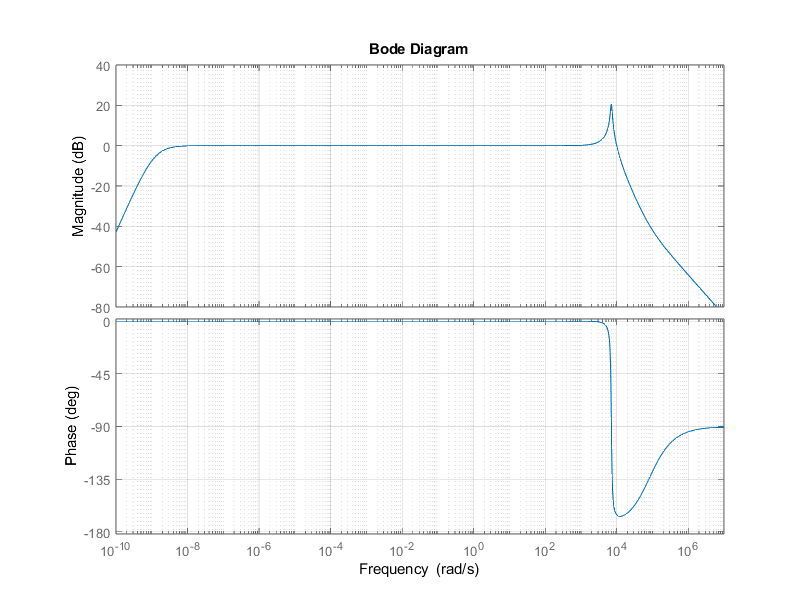

figure('Position', [100, 100, 800, 600]);
bode(x1x2primaprima)
hold on
grid on

hold off




A_aument = [A,[0;0;0;0;K_motor/m_em;-K_motor/m_shaker];0 0 0 0 -K_motor/L K_motor/L -R/L];
Bu_nueva = [0 0 0 0 0 0 1/L]';
Bd_nueva = [Bd;0];
B_nueva = [Bu_nueva Bd_nueva];

col_corr = [zeros(7,1); K_motor/m_em;-K_motor/m_shaker];
C_aument = [Cc col_corr; 0 0 0 0 0 0 1];
D_aument = [D;[0 0]];
sys2 = ss(A_aument,B_nueva,C_aument,D_aument);
f_transf2 = tf(sys2);


co = ctrb(A_aument, Bu_nueva);  % matriz de controlabilidad
rank_co = rank(co);


ob = obsv(A_aument, C_aument(8,:)); % Por que usar C_aument(8,:), que es la fila de la aceleracion que mido, hace que dé rango 2?
rank_ob = rank(ob);

if rank_ob == size(A_aument,1)
    disp('El sistema es observable.');
else
    disp(['NO es observable. Rank = ', num2str(rank_ob)]);
end

NO es observable. Rank = 2


ob_reducida = rref(ob);



K_motor_virtual = K_motor;

wc_corr = 5000; %Frecuencia de corte
R_control = wc_corr * L;
Amp =0.5*g; %[m/s^2]
f0 = 15; %[Hz] %Para f0 = 45, a altas amplitudes anda bien la random, aunque es recomendable usar wp = 15 porque no funciona para todos los cubesats y amplitudes.
zita_cont = 0.7;
wp = wpfreq(f0);

if Amp < 0.3*g
    wp = wp/2;
end
ba = m_em*(2*zita_cont+1)*wp

ba = 37.2240

ksi = m_em*(2*zita_cont+1)*wp^2*10

ksi = 6.1420e+03

ksia = m_em*wp^3

ksia = 4.2226e+03


%% MUESTREO
fs = 10e3; % [Hz]
Ventana = round(fs/f0);
%Ventana = 1000; %Sweep y random
if f0 <= 100
    ZOH = 10/fs;
else
    ZOH = 1/fs;
end


%% -------------------------------
% OBSERVADOR DE ESTADOS
% -------------------------------
% Indices de los estados a mantener: pos2 (2), vel2 (5), corriente (7)
% %% Matrices reducidas del sistema
% idx_obs = [2 5 7];  % pos2, vel2, i
% A_reduc = A_aument(idx_obs, idx_obs);
% B_reduc = Bu_nueva(idx_obs);
% C_reduc = A_reduc(2,:);  % Observamos aceleración del plato (estado 2)
% 
% %% Construcción del sistema aumentado con acción integral
% Alol = [A_reduc, [0;1;0];     % añadimos estado integrador
%          C_reduc, 0];          % dinámica del integrador
% Blol = [B_reduc; 0];          % entrada al sistema aumentado
% Bdlol = [0 1 0]';
% Clol = [C_reduc, 0];          % salida
% 
% %% Parámetros de diseño (ruido)
% Q_kal = diag([1e-7 1e-7 1e-3 1000]);  % incertidumbre del proceso
% R_kal = 1;                         % ruido del sensor
% 
% %% Filtro de Kalman (observador)
% [L_kal, P, E] = lqe(Alol, eye(4), Clol, Q_kal, R_kal);
% 
% % Separación de la ganancia
% Lobs = L_kal(1:3);  % ganancia para estados reales
% Li    = L_kal(4);    % ganancia para el integrador
% 
% disp('Ganancia del observador Kalman (estados):')
% disp(Lobs)
% disp('Ganancia del integrador:')
% disp(Li)

%% OBSERVADOR CON ACKER
% %% -------------------------------
% % OBSERVADOR DE ESTADOS
% % -------------------------------
% % Indices de los estados a mantener: pos2 (2), vel2 (5), corriente (7)
idx_obs = [2 5 7];

% Extraer submatrices de A y B
A_reduc = A_aument(idx_obs, idx_obs);      % 3x3
B_reduc = Bu_nueva(idx_obs);               % 3x1
C_reduc = A_reduc(2,:);         % 1x3, aceleración del plato
%p_obs = [-5000, -5000, -5000]  % Polos rápidos (pero no más que el lazo de corriente)

%Lobs = acker(A_reduc', C_reduc', p_obs)'
%disp('Ganancia del observador L:');
%disp(Lobs);


%% GANANCIA INTEGRAL
tol = 1e-7;
Alol = [A_reduc [0 1 0]';C_reduc 0]

Alol = 	1.0e+07 *

         0    0.0000         0         0
   -7.0939   -0.0001    0.0000    0.0000
         0   -0.0027   -0.0002         0
   -7.0939   -0.0001    0.0000         0


Blol = [B_reduc;0]

Blol =          0
         0
  526.3158
         0


Bdlol = [0 1 0]';
Clol = [C_reduc 0]

Clol = 	1.0e+07 *

   -7.0939   -0.0001    0.0000         0



[Abar_reduc,Bbar_reduc,Cbar_reduc,T_reduc,k_reduc] = obsvf(Alol,Blol,Clol, tol)

Abar_reduc = 	1.0e+07 *

   -0.0000   -0.0001    0.0013    6.2363
   -0.0001   -0.0001    0.0024   -3.3809
   -0.0000    0.0000   -0.0000   -7.0940
    0.0000   -0.0000    0.0000   -0.0001


Bbar_reduc =   250.2904
  462.9931
   -0.6298
    0.0004


Cbar_reduc = 	1.0e+07 *

    0.0000    0.0000    0.0000    7.0939


T_reduc =     0.0000   -0.0006    0.4756    0.8797
    0.0000   -0.0010    0.8797   -0.4756
    0.0000   -1.0000   -0.0012   -0.0000
   -1.0000   -0.0000    0.0000         0


k_reduc =      1     1     1     1



p_obs_int = [-10000 -10000 -10000 -R/L]; 

Lobs_aum = acker(Alol', Clol', p_obs_int)';

Li = Lobs_aum(end);
Lobs = Lobs_aum(1:end-1,1);


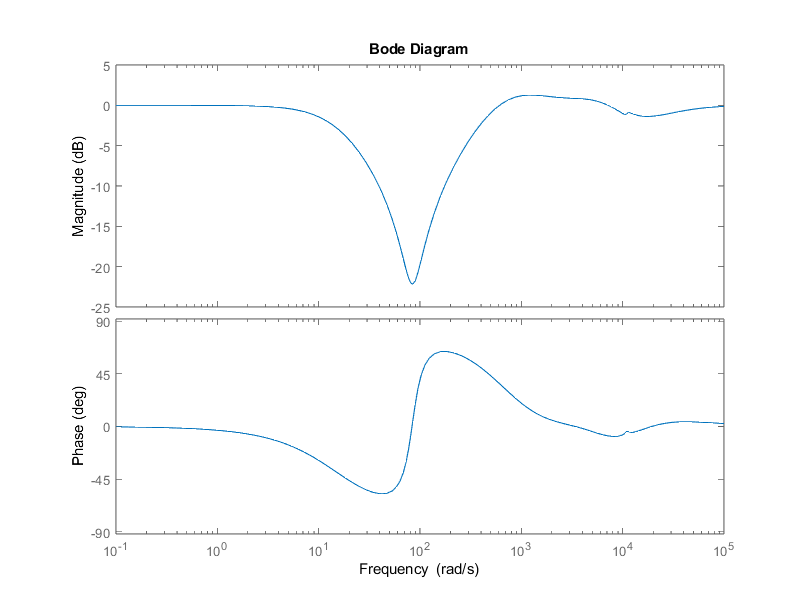



%% Prueba
 M_obs = [A_reduc-Lobs*C_reduc Bdlol; -Li*C_reduc 0];
 sys_obs_i = tf(ss(M_obs, Blol,[0 0 1 0],0));
 iRealVsMed = f_transf2(10,1)/sys_obs_i;
 
 %[obs_i_num,obs_i_den] = tfdata(iRealVsMed,'v');
 
 iRealVsMed_disc = c2d(iRealVsMed, 1/fs, 'tustin');
 [obs_i_num,obs_i_den] = tfdata(iRealVsMed_disc,'v');
 
 bode(iRealVsMed)

%  figure(2)
 %step(sys_obs_i)
 
 sys_obs_x2 = tf(ss(M_obs, Blol,[1 0 0 0],0));
 x2RealVsMed = f_transf2(2,1)/sys_obs_x2;
 %figure(3)
% bode(x2RealVsMed)
 
 [obs_x2_num,obs_x2_den] = tfdata(x2RealVsMed,'v');



%% SENSOR ACELEROMETRO MEMS
sens_mems = 20e-3/g; % [V/m/s2]
Vcc = 5 ; % [V]
f_mems = 21000; %[Hz]
w_mems = f_mems*2*pi;
zita_mems = 0.12;
num_mems = (w_mems)^2;
den_mems = [1,2*zita_mems*w_mems, w_mems^2];
H = tf(num_mems,den_mems);
%bode(H)


NSD_mems = 30e-6*g; %[m/s2/sqrt(Hz)]
PSD_mems = NSD_mems^2;
NoisePower_mems= PSD_mems * (fs / 2);  % Total power



%% SENSOR ACELERÓMETRO PIEZOELÉCTRICO

sens_piezo = 10e-3; % V/m/s2
% f_piezo = 18000;
% w_piezo = f_piezo*2*pi;
zita_piezo = 0.7;
f_low_piezo = 0.3;
w_low_piezo = f_low_piezo*2*pi;

% Numerador y denominador del sistema
num_piezo =   [1 0];                         % s en el numerador
den_piezo = [1 w_low_piezo];      % (s + w_low)*(s^2 + 2zwn*s + wn^2)

% Crear función de transferencia
H_piezo = tf(num_piezo, den_piezo);

NSD_piezo = 15e-6*g; %[m/s2/sqrt(Hz)]
PSD_piezo = NSD_piezo^2;
NoisePower_piezo= PSD_piezo * (fs / 2);  % Total power


%bode(H_piezo)


%% Desacople de componente de continua

R_des = 10000;     % 10 kOhm
C_des = 10e-6;    % 10 uF
s = tf('s');

H_des = (s*R_des*C_des) / (1 + s*R_des*C_des);
[num_des,den_des] = tfdata(H_des,'v');
%bode(H_des)
%title('Filtro RC pasa altos (desacople DC)')
%grid on



%% Filtro pasabajo antialiasing
f_c_pb1 = 7000; %[Hz]
R_pb1 = 15000; %[ohm]
C_pb1 = 1/(2*pi*f_c_pb1*R_pb1);

R_pb2 = 5000; %[ohm]
C_pb2 = C_pb1; %
f_c_pb2 = 1/(2*pi*C_pb2*R_pb2);

H_antial1 = tf([0 1],[R_pb1*C_pb1 1]);
H_antial2 = tf([0 1],[R_pb2*C_pb1 1]);

H_antial = H_antial1 * H_antial2;


%pasaalto = tf([1 0], [1 1])
%H_antial = H_antial * pasaalto
[num_anti,den_anti] = tfdata(H_antial,'v');
%bode(H_antial)

%% ADC
n_adc = 12; %bits
Vmin_ADC = 0; % [V]
Vmax_ADC= 3.3;% [V]


%% Filtro pasabanda
if f0 <= 10
    deltaf = 5;
else
    deltaf= 10;
end
N   = 10;   % Order
Fc1 = f0-deltaf;  % First Cutoff Frequency
Fc2 = f0+deltaf;  % Second Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, fs);
Hd_pasabanda = design(h, 'butter');
sos = Hd_pasabanda.sosMatrix;
scaleV = Hd_pasabanda.ScaleValues;

%% RANDOM VIBRATIONS
rms_rand = 4*g;

function wp = wpfreq(f)
    % Tabla de frecuencia (Hz) y valores correspondientes de wp
    freq_table = [ ...
          5,  10,  20,  25,  30,  40,  50,  60,  70,  80, ...
         90, 100, 200, 300, 400, 500, 600,700,800, 900, 1000, 1100,1200, 1300, 1450, 1500,1800, 2000];

    wp_table = [ ...
         20,  15,  18,  20,  22,  25,  30,  25,  30,  30, ...
         30,  40,  50,  50,  35, 35,40,60, 80, 80,  100, 100,100, 100, 100,  120,90,  100];

    % Interpolación lineal
    wp = interp1(freq_table, wp_table, f, 'linear', 'extrap');
end
